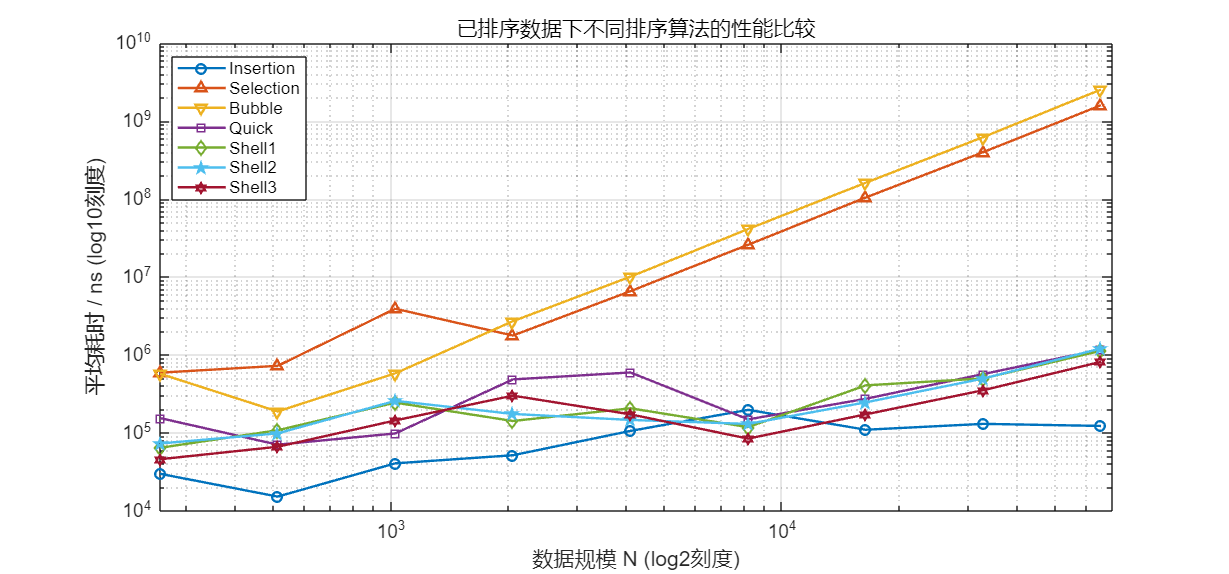

% 数据规模
N = [256 512 1024 2048 4096 8192 16384 32768 65536];

% 各算法平均耗时（纳秒）
Insertion = [29820 15200 40600 51580 105900 197220 109580 130380 122580];
Selection = [591720 724020 3914140 1772340 6587260 25941040 104754080 400645160 1603071540];
Bubble    = [573900 188000 580520 2706020 10099560 41305060 162031880 625886040 2546467180];
Quick     = [154800 70420 98260 484720 595680 148680 273440 568600 1174200];
Shell1    = [64260 107980 244100 141880 206460 118240 406620 499680 1131700];
Shell2    = [73000 98360 257380 174720 146420 130100 246220 497800 1211380];
Shell3    = [45820 66300 144280 300180 172580 84320 172700 352440 815760];

% 打开大尺寸窗口
figure('Position',[100 100 1500 700]);

% 绘图（使用 log-log 坐标）
loglog(N, Insertion, '-o','LineWidth',1.5,'DisplayName','Insertion'); hold on;
loglog(N, Selection, '-^','LineWidth',1.5,'DisplayName','Selection');
loglog(N, Bubble,    '-v','LineWidth',1.5,'DisplayName','Bubble');
loglog(N, Quick,     '-s','LineWidth',1.5,'DisplayName','Quick');
loglog(N, Shell1,    '-d','LineWidth',1.5,'DisplayName','Shell1');
loglog(N, Shell2,    '-p','LineWidth',1.5,'DisplayName','Shell2');
loglog(N, Shell3,    '-h','LineWidth',1.5,'DisplayName','Shell3');

% 坐标轴与标签
xlabel('数据规模 N (log2刻度)');
ylabel('平均耗时 / ns (log10刻度)');
title('已排序数据下不同排序算法的性能比较');
legend('Location','northwest');
grid on;

% 优化图像显示
set(gca,'FontSize',12);
xlim([256 70000]);